# C&S8.1 Laminar Flow of a Newtonian Fluid in a Horizontal Pipe

## Shooting Method for 2-point Boundary Value Problem (Revised)

## Chemical Engineering Summer School Workshop Objectives

- Make a copy of this template and then modify this template to solve this problem with a internal link.

- Discuss the difficulties that you had in modifying this template.

## Objectives

- Derive a momentum balance for laminar flow in a pipe

- Numerically integrate a 2nd order ODE by splitting it into two first order ODE's and using a trial and error technique to obtain a solution.

- Add a portion of code to perform the trial and error techique used above.

For C&S 8.1 Use a $\frac{\Delta P}{L}=5 \frac{Pa}{m}$ This will result in a Reynolds number of about 1000 (instead of the turbulent flow value obtained from the text problem)

## Cutlip & Shacham 8.1 Laminar Pipe Flow Modified (remember to Read de Nevers 6.3 and Geankoplis 4.4B)

a)   Derive the unsteady-state momentum balance for pipe flow.

b)   Derive the analytical solution giving the velocity and stress profiles.

c)   Derive the analytical solution for flowrate (remember to Read de Nevers 6.3).

d)   Obtain velocity and stress profiles from a numerical solution of the momentum balance for laminar pipe flow.  (also given below as equations 7 and 8). 

- This needs to be solved using a trial and error procedure to find the solution.

- It is recommended that you obtain an estimated first and second value of velocity at the centerline and then interpolate for each additional trial.  

- Give a table showing all of your iterations.

- For the properties of water at 25°C use $\mu=8.937\times10^{-4} kg/m/s$`, `$\rho=1000kg/m^3
$`.  `Again for the pressure drop use $\frac{\Delta P}{L}=5 \frac{Pa}{m}$`  The `radius of the pipe is $R=0.009295 m$`. `

e)    Add a section of code that will perform the trial and error processes to obtain the solution.  It is suggested that you use a while loop for this.

f)    Solve Cutlip & Shacham 8.1 modified using COMSOL Multiphysics.  Compare the analytical solution from  above with the solutions obtained from python and COMSOL. This comparison should be done using 2 graphs one for velocity and the other shear stress.  On each graph you should use 3 line styles to distinguish between analytical and numerical solutions of COMSOL and python.  For part c again compare the 3 solutions.  For COMSOL you will need to perform a line integration.

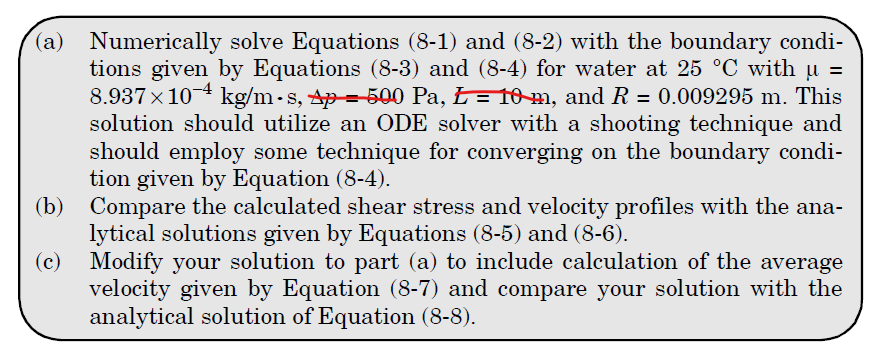

### C&S8.1 Partial Solution (modified from above)

Newtonian fluid flow in a horizontal pipe results in a linear shear stress profile and a parabolic velocity profile.  You will solve this problem using ODE solvers which can only solve first order ODE’s.  Thus you must make the 2nd order ODE into 2 first order ODE’s.  The next problem that you encounter is that you need a boundary condition for each ODE.  But you only have boundary conditions of one variable at the first surface and the second variable at the second surface.  This results in needing a shooting technique to guess the boundary condition of one of the variables and then integrate the equations and check to see if the solution at the second boundary matches the boundary condition that is given.  If not guess a second time and check the boundary conditions.  Then obtain the third guess by interpolation (secant method) or an automated code.  

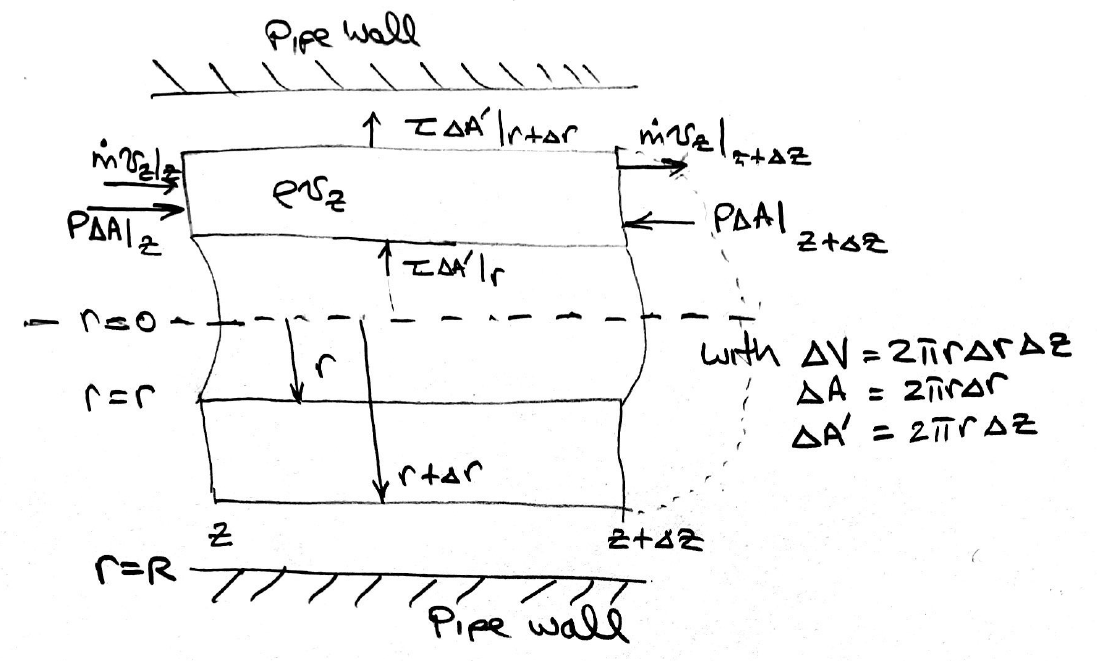

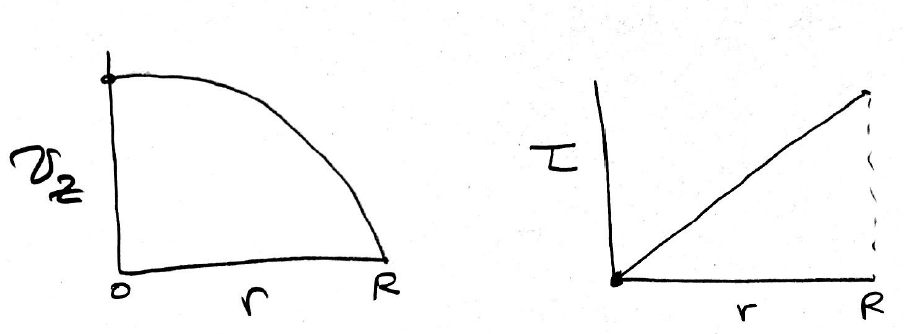

This problem in C&S8.1 which is similar to C&S 6.4 and 6.5. 

The momentum balance on the on a control volume in a pipe of $\Delta V=2\pi r \Delta r \Delta z$`:`

Differential momentum Balance in $z$ direction


$$$$\Delta V \frac {(\partial \rho  v_z)}{\partial t}= \dot{m} v_z |_{z}-\dot{m} v_z |_{z+\Delta z}+P \Delta A_c|_{z}-P \Delta A_c |_{z+\Delta z} +\tau _{rz} \Delta A_r |_r -\tau _{rz} \Delta A_r |_{r+ \Delta r}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(1)$$$$
  

With $$\Delta A_c=2\pi\ r\Delta r$$ and $$\Delta A_r=2\pi\ r \Delta z$$ and using the definition of $$\dot{m}=\rho\overline{v}A_c$$

Dividing by the control volume and taking the limit of $\Delta V \to 0$`:`


$$$$\frac {\partial m v_z}{\partial t}=- \frac{\partial (\rho \overline{v} v_z)}{\partial z} -\frac{\partial P}{\partial z}-\frac{\partial (\tau_{rz}r)}{r\partial r}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(2)$$$$


At steady state and knowing from experiments that $$\frac{dP}{dz}=constant$$


$$$$\frac {\partial m v_z}{\partial t}= 0 = - \frac{\partial (\rho \overline{v} v_z)}{\partial z} -\frac{ dP}{dz}-\frac{\partial (\tau_{rz}r)}{r\partial r}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(3)$$$$


Evaluating the first term we will use a mass balance on a streamline:


$$$$\left.\ \ \dot{m}\right|_{in}=\left.\ \ \dot{m}\right|_{out}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(4)$$$$


Which results in $$\rho v_z A = \rho v_z A$$ and for a constant density and streamline area the result is that $v_z$ is a constant and the term $\frac{\partial(\rho \overline{v} v_z)}{dz}=0$ and is removed from the equation.

The remaining terms are 


$$$$\frac{\partial (\tau_{rz}r)}{r\partial r}= \left(-\frac{d P}{dz }\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(5)$$$$


The constituitive equation for this geometry is given as


$$$$\tau_{rz}=-\mu\frac{\partial v_z}{\partial r}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(6)$$$$


We will rearrange the consitutive equation (Eqn 6) into a differential equation:


$$$$\frac{\partial v_z}{\partial r}=-\frac{\tau_{rz}}{\mu}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(7)$$$$


Equation 5 can be rearranged to give only the derivative on the left hand side


$$$$\frac{\partial (\tau_{rz}r)}{\partial r}= \left(-\frac{ dP}{ dz}\right)r\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(8)$$$$


The result is that we can solve the two ode's given by equations 7 and 8 numerically using an ODE solver.

The variable rTAUz will be used instead of the two variables $r\tau_{rz}$

To extract the stress an extra equation is added 


$$$$\tau_{rz}=\frac{r\tau_{rz}}{r}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(9)$$$$


This equation will cause problems at $r=0$ so an if then statement is added to handle the start of the integration and prevent division by zero.

Looking at the figures of the velocity and stress profiles given above, the boundary condtions are $v_z |_{r=0}=max$ and  $\tau _{rz} |_{r=0}=0$ and

$v_z |_{r=R}=0$ and  $\tau _{rz} |_{r=R}= max$ Unfortunately we need to know both values of $v_z$* and *$\tau_{rz}$ at ${r=0}$ to start integrating, but we only know $\tau_{rz}=0$ at ${r=0}$`. `But fortuately we know the value of $v_z$`  at `${r=R}$ which is zero! This is called a **split value boundary problem**.  This means we will need to guess the value of $v_z|_{r=0}$ and then check to see that at $v_z|_{r=R}=0$`.`

The values of the constants are $R=0.009295\, m \;L=10 \,m\;\mu=8.937\times{10}^{-4}\frac{kg}{m\ s}\;  \rho=1000 \frac{kg}{m^3}\; \Delta P=50 \frac{Pa}{m}$

# General MATLAB ODE solver flowchart

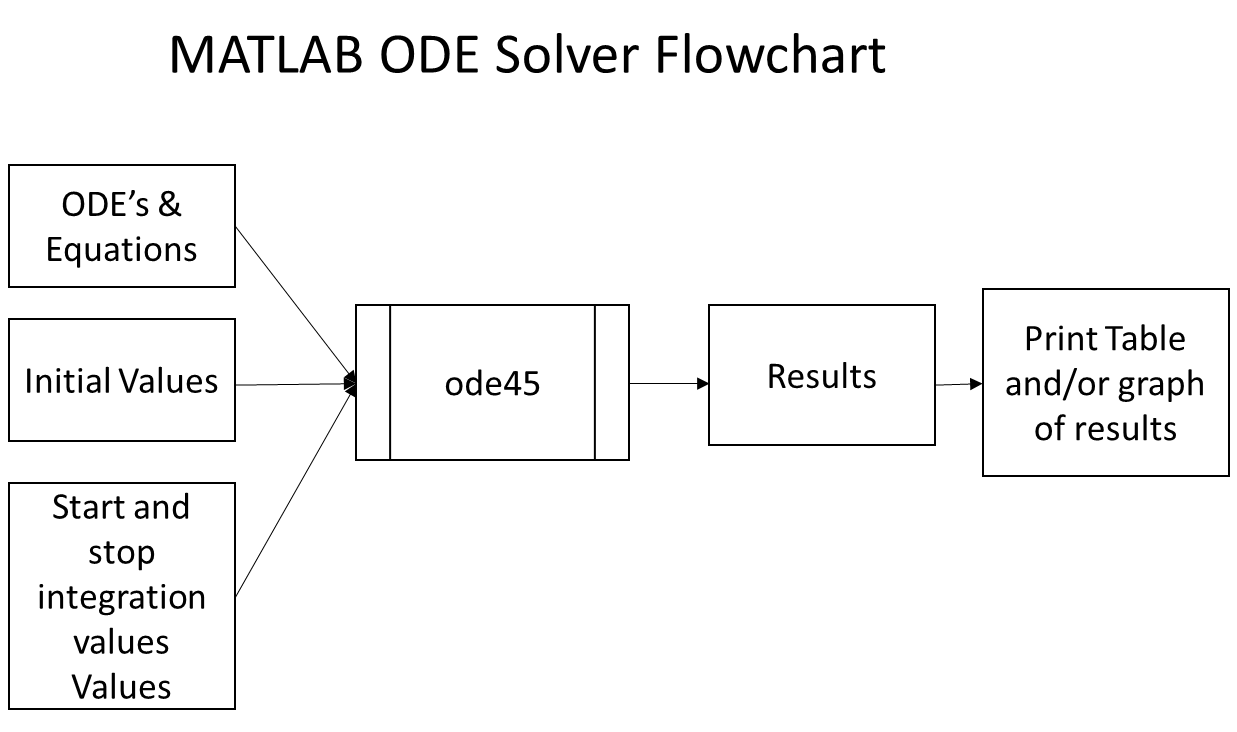

## MATLAB ODE function

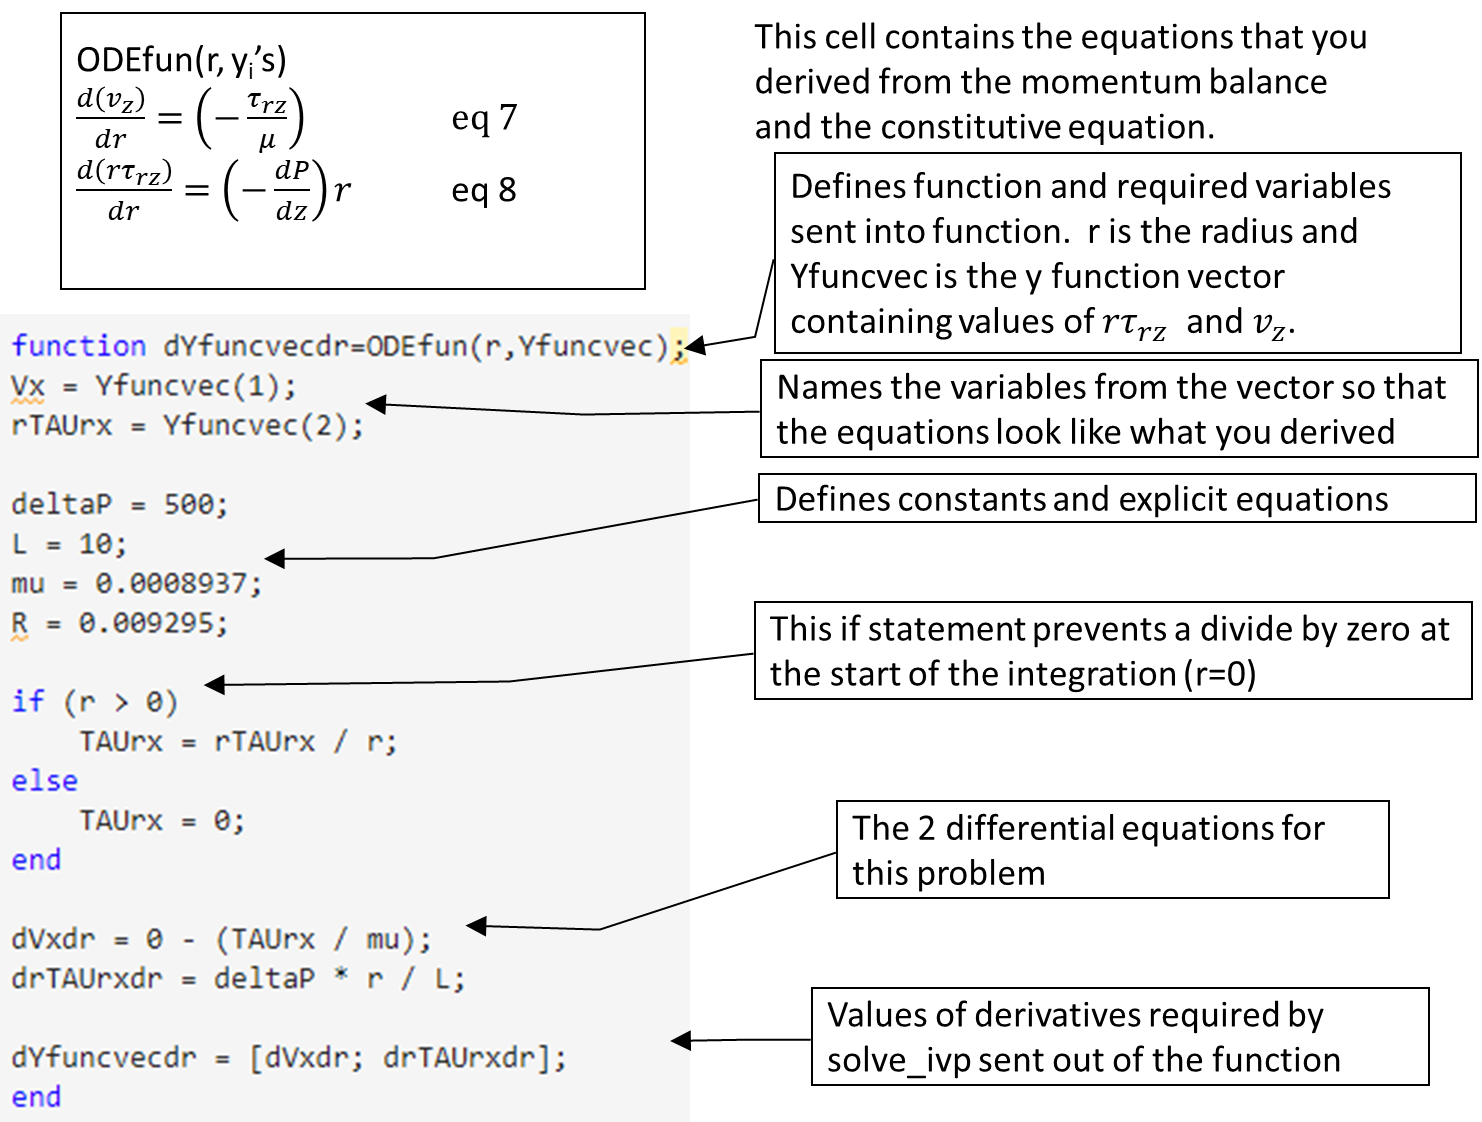

This is an example of the function that contains the differential equations which is located at the end Functions

## Clear the output in the "command window" using clc;

clear, clc, format short g, format compact

The following is a test of the ODEfun to see if there are any obvious errors.  We expect all the derivatives to be zero at $r=0$ and they are!

%test of function ODEfun
tspan = [0 0.009295]; % Range for the independent variable
y0 = [1; 0]; % Initial values for the dependent variables
sol=ODEfun(0,y0); 
disp(sol); 

     0
     0


## Split Boundary Value problem

If we guess it and integrate we will know we are correct when if $v_z|_{r=R}=0$

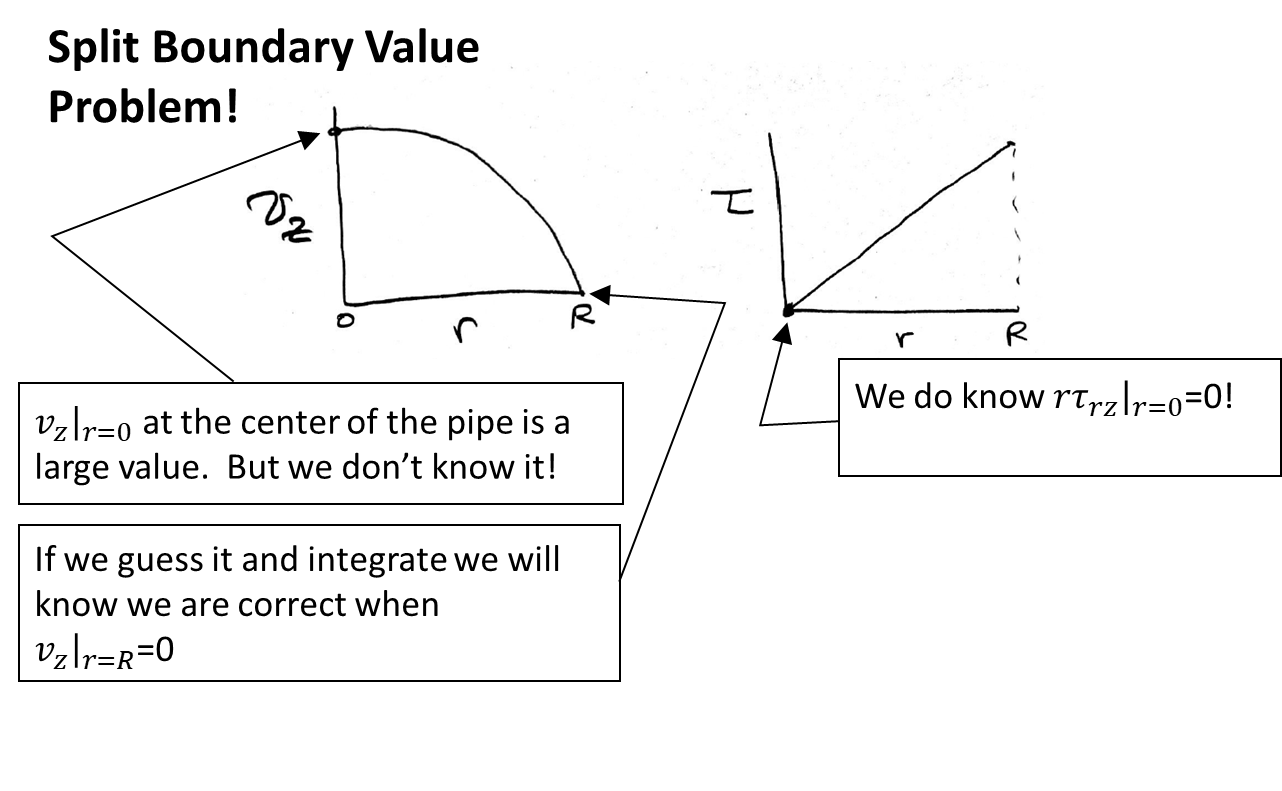

Estimation of the first guess of the velocity at r=0 can be made from the first integration of  $$$\frac{\partial v_z}{\partial r}=-\frac{\tau_{rz}}{\mu}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(7)$$$

Which gives $$${\tau_{rz}}=\frac{R}{2}\frac{\Delta P}{L}=\frac{0.009295 m}{2}5=0.02324 Pa\;$$$

and for an approximation using $$$\frac{dv_z}{dr}\approx \frac{\Delta v_z}{\Delta r}=\frac{\tau_{rz}}{\mu}$$$

Then $v_{max}$


$$$$v_{max}=\frac{0.2324\,Pa}{8.937\times{10}^{-4}\frac{kg}{m\ s}}0.009295\,m=0.242\,m/s$$$$


And then use as the second guess 0.3 m/s.

approxTau=0.009295/2*5

approxTau =      0.023237

approxVmax=approxTau/8.937e-4*0.009295

approxVmax =       0.24168

Solve this twice with the 2 estimated values of $v_z$ at $r=0$.

tspan = [0,0.009295]; % Range for the independent variable 
y0 = [approxVmax, 0]; % Initial values for the dependent variables
[t,y]=ode45(@ODEfun,tspan,y0); %solve the ODE with first guess 

y0 = [0.3, 0]; % Initial values for the dependent variables
[t2,y2]=ode45(@ODEfun,tspan,y0);%solve the ODE 
disp('   Trial    Vz|r=0       Vz|r=wall');

   Trial    Vz|r=0       Vz|r=wall


fprintf('%2.0f\t     %10.8f\t  %13.4e\t \n',1,y(1,1),y(end,1));

 1	     0.24168352	     1.2084e-01	 


fprintf('%2.0f\t     %10.8f\t  %13.4e\t \n',2,y2(1,1),y2(end,1));

 2	     0.30000000	     1.7916e-01	 


So have a go at this and see how many guesses it would take to get a velocity at the wall less than 1e-6. Use the cells below to do these calculations.

Trial 3 with a new value in y0=[newVz3,0]

Trial 4 with a new value in y0=[newVz4,0]

Trial 5 with a new value in y0=[newVz5,0]  and repeat until v(end,1)<1e-6

## Smart Guessing or iterations

Hopefully you have seen that just guessing the velocity at $r=0$ results in a large number of iterations.  But we are smarter than that!  Your third guess should have been from an interpolation of the first 2 trials.  

Let's interpolate.  Solve for the $v_z|_{r=0}$ that gives $v_z|_{r=\text{Wall}}=0$ using the 2 points above as the slope.


$$$$\frac{0.3-0.24168}{0.17916-0.12084}=\frac{0024168-NEXTv_z}{0.12084-0}$$$$


`solving for `$\text{NEXT}v_z$


$$$$\text{NEXT}v_z=\frac{0.3-0.24168}{0.17916-0.12084}{(0-0.17916)}+0.3$$$$


gives our 3rd guess.

NEXTvz=(0.3-0.24168)/(0.17916-0.12084)*(0-0.17916)+0.3

NEXTvz =       0.12084

y0 = [NEXTvz, 0]; % Initial values for the dependent variables
[t3,y3]=ode45(@ODEfun,tspan,y0);%solve the ODE 
fprintf('%2.0f\t     %10.8f\t  %13.4e\t \n',3,y3(1,1),y3(end,1));

 3	     0.12084000	    -1.7604e-06	 


Wow only 1 interpolation and we immediately drop to a value of $v_z$ at the wall of near zero!  This results because we used a very good estimate of the maximum velocity.  This will require at most only one more interpolation:

NEXTvz=(NEXTvz-0.24168)/(y3(end,1)-0.12084)*(0-y3(end,1))+NEXTvz

NEXTvz =       0.12084

y0 = [NEXTvz, 0]; % Initial values for the dependent variables
[t4,y4]=ode45(@ODEfun,tspan,y0);%solve the ODE 
fprintf('%2.0f\t     %10.8f\t  %13.4e\t \n',4,y4(1,1),y4(end,1));

 4	     0.12084176	    -2.5645e-11	 


Here in the 4th iteration (2nd interpolation) we get a value of less than 1e-6!

## Automated Calculation of the trials

Why do this by hand?  We are sitting at a computer.  Why not tell the computer to do this work!

Automating the interpolation process is called the secant method. Using our first 2 guesses of the value of $v_z |_{r=0}$ we will calculate the $v_z$ at the wall.  The velocity at the wall should be zero.  In many cases the value that we looking for is not zero and then you will need to subtract it from the value to still look for zero.  We will call this the error or err.  So this looks silly since we are looking for zero so we are subtracing zero! 


$$$$err(v_{z_{k}})=\left. v_z \right|_{r=R}-0$$$$
 

Again the **secant method** is just a **linear interpolation between pairs of points** .  

In this case the pairs of points are the $(v_z |_{r=0}$`, `$v_z |_{r=R}$`) or `$(y_0, err( y_0 ))$


$$$$y_{0_{k+1}}=y_{0_k}-err(y_{0_k})$$$$



$$$$y_{0_{k+1}}=y_{0_k}-err(y_{0_k})\frac{ y_{0_k}-y_{0_{k-1}} } {err(y_{0_k})-err(y_{0_{k-1}})}$$$$


Two initial values or guesses of $y_0$ are needed.

Below is the automatic iteration calculations code

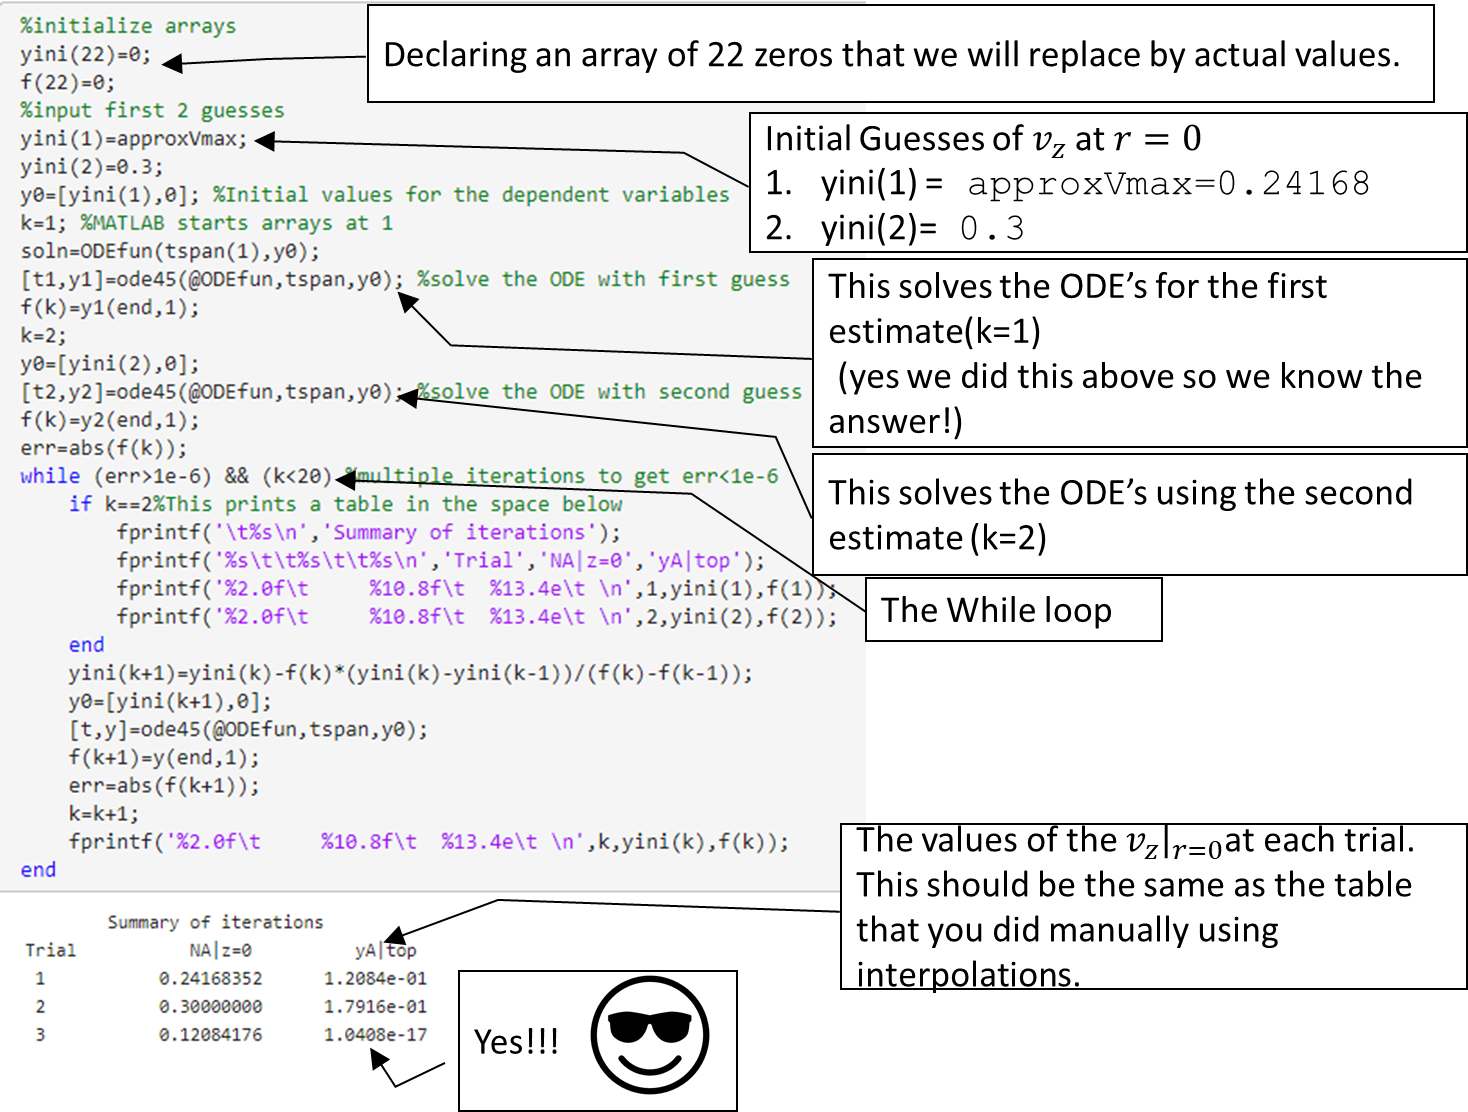

The following is the flow chart for the While Loop

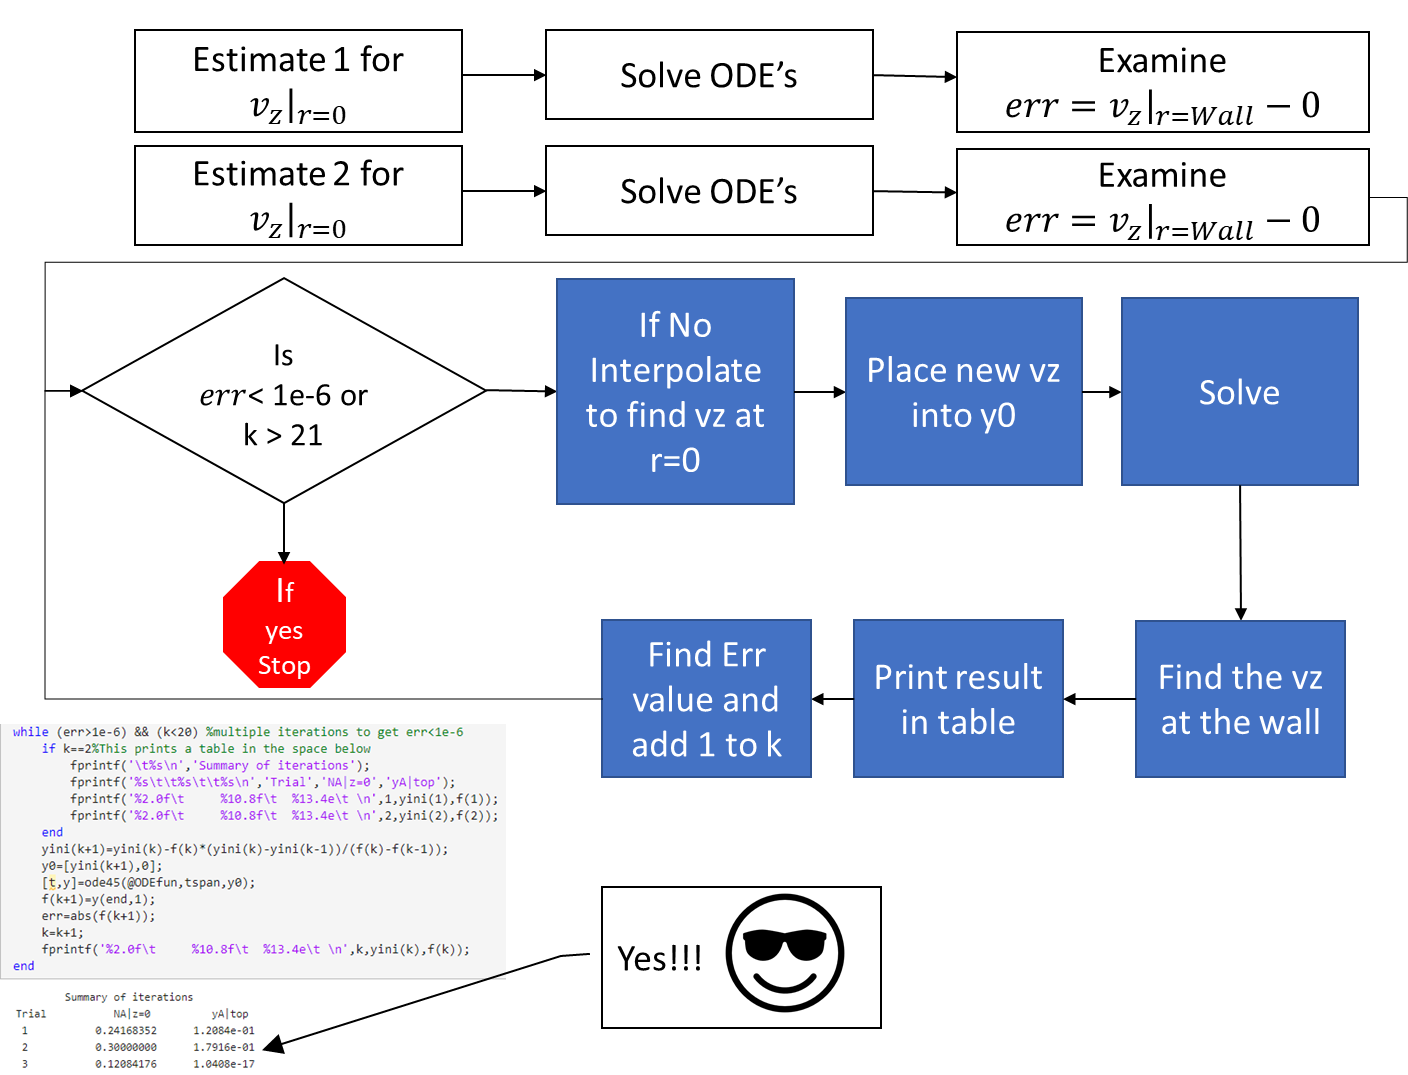

%initialize arrays
yini(22)=0;
f(22)=0;
%input first 2 guesses
yini(1)=approxVmax;
yini(2)=0.3;
y0=[yini(1),0]; %Initial values for the dependent variables
k=1; %MATLAB starts arrays at 1
soln=ODEfun(tspan(1),y0);
[t1,y1]=ode45(@ODEfun,tspan,y0); %solve the ODE with first guess
f(k)=y1(end,1);
k=2;
y0=[yini(2),0];
[t2,y2]=ode45(@ODEfun,tspan,y0); %solve the ODE with second guess
f(k)=y2(end,1);
err=abs(f(k));
while (err>1e-6) && (k<20) %multiple iterations to get err<1e-6
    if k==2%This prints a table in the space below
        fprintf('\t%s\n','Summary of iterations');
        fprintf('%s\t\t%s\t\t%s\n','Trial','NA|z=0','yA|top');
        fprintf('%2.0f\t     %10.8f\t  %13.4e\t \n',1,yini(1),f(1));
        fprintf('%2.0f\t     %10.8f\t  %13.4e\t \n',2,yini(2),f(2));
    end
    yini(k+1)=yini(k)-f(k)*(yini(k)-yini(k-1))/(f(k)-f(k-1));
    y0=[yini(k+1),0];
    [t,y]=ode45(@ODEfun,tspan,y0);
    f(k+1)=y(end,1);
    err=abs(f(k+1));
    k=k+1;
    fprintf('%2.0f\t     %10.8f\t  %13.4e\t \n',k,yini(k),f(k));
end

	Summary of iterations


Trial		NA|z=0		yA|top


 1	     0.24168352	     1.2084e-01	 


 2	     0.30000000	     1.7916e-01	 


 3	     0.12084176	     1.0408e-17	 


## Printing a table of Results

numrows=11;
teval = linspace( tspan(1),tspan(2) , numrows );
[t,y]=ode45(@ODEfun,teval, y0);
TAUrzANAL(11)=0;
VzANAL(11)=0;
TAUrz(11)=0;
deltaP = 5;
L = 1;
mu = 0.0008937;
R = 0.009295;

for i=1:numrows
    if i==1
        fprintf('%s\t\t%s\t\t%s\t %s\t %s\n','     r',        '    vz', '    vzANAL','  Taurz',' TaurzANAL');
        fprintf('    %s\t\t    %s\t   %s\t %s\t   %s\n','(m)','(m/s)', '(m/s)',      '   (Pa)' ,'(Pa)');
    end
    TAUrzANAL(i) = deltaP / (2 * L) * t(i);
    VzANAL(i) = deltaP * R ^ 2 / (4 * mu * L) * (1 - ((t(i) / R) ^ 2));
    if (t(i) > 0)
        TAUrz(i) = y(i,2) / t(i);
    else
        TAUrz(i) = 0;
    end
    fprintf('%8.4f\t %8.4f\t  %8.4f\t %8.4f \t%8.4f\t\n', t(i),y(i,1),VzANAL(i),TAUrz(i),TAUrzANAL(i));              %\t is a tab, \n new line,
   
end

     r		    vz		    vzANAL	   Taurz	  TaurzANAL


    (m)		    (m/s)	   (m/s)	    (Pa)	   (Pa)


  0.0000	   0.1208	    0.1208	   0.0000 	  0.0000	
  0.0009	   0.1196	    0.1196	   0.0023 	  0.0023	
  0.0019	   0.1160	    0.1160	   0.0046 	  0.0046	
  0.0028	   0.1100	    0.1100	   0.0070 	  0.0070	
  0.0037	   0.1015	    0.1015	   0.0093 	  0.0093	
  0.0046	   0.0906	    0.0906	   0.0116 	  0.0116	
  0.0056	   0.0773	    0.0773	   0.0139 	  0.0139	
  0.0065	   0.0616	    0.0616	   0.0163 	  0.0163	
  0.0074	   0.0435	    0.0435	   0.0186 	  0.0186	
  0.0084	   0.0230	    0.0230	   0.0209 	  0.0209	
  0.0093	   0.0000	    0.0000	   0.0232 	  0.0232	


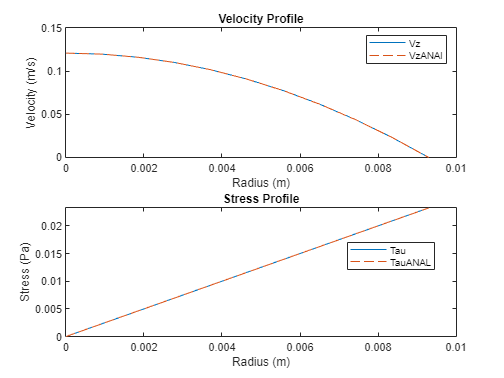

%plot results
figure(1)
subplot(2,1,1)
plot(t,y(:,1),'-',t,VzANAL,'--')
title('Velocity Profile')
xlabel('Radius (m)')
ylabel('Velocity (m/s)')
legend('Vz','VzANAl')

subplot(2,1,2)
plot(t,y(:,1),'-',t,VzANAL,'--')
plot(t,TAUrz,'-',t,TAUrzANAL,'--')

title('Stress Profile')
xlabel('Radius (m)')
ylabel('Stress (Pa)')
legend('Tau','TauANAL','Location', 'Best')

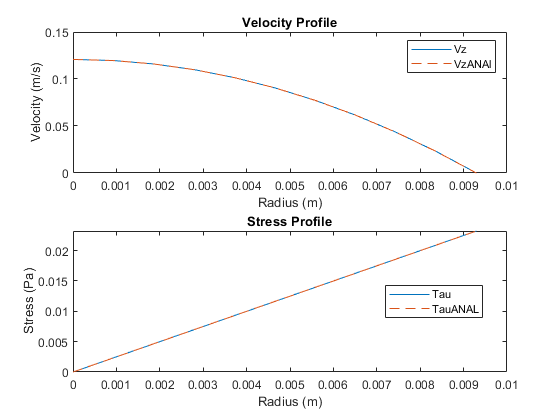

%plot results
figure(2)
subplot(2,1,1)
plot(t,y(:,1),'-')
hold on
plot(t,VzANAL,'--')
hold off
title('Velocity Profile')
xlabel('Radius (m)')
ylabel('Velocity (m/s)')
legend('Vz','VzANAl')

subplot(2,1,2)
plot(t,TAUrz,'-')
hold on
plot(t,TAUrzANAL,'--')
hold off

title('Stress Profile')
xlabel('Radius (m)')
ylabel('Stress (Pa)')
legend('Tau','TauANAL','Location', 'Best')

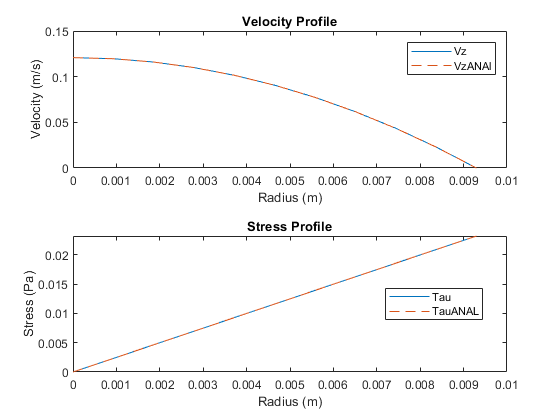

figure (3)
tiledlayout(2,1)
nexttile
plot(t,y(:,1),'-')
hold on
plot(t,VzANAL,'--')
hold off
title('Velocity Profile')
xlabel('Radius (m)')
ylabel('Velocity (m/s)')
legend('Vz','VzANAl')

nexttile
plot(t,TAUrz,'-')
hold on
plot(t,TAUrzANAL,'--')
hold off

title('Stress Profile')
xlabel('Radius (m)')
ylabel('Stress (Pa)')
legend('Tau','TauANAL','Location', 'Best')

## Further work and Reflections

Make a copy of this template and solve again with a linear temperature profile in which the pipe wall is at 45°C and the centerline ($$r=0$$) is at 25°C.  You can use the following correlations for density and viscosity of water:  $$$\rho=46.048+9.418T-0.0329T^2+4.882\times10^{-5}T^3-2.895\times10^{-8}T^4[=]\frac{kg}{m^3}$$  $ with $T$ in Kelvin $$$\mu=\exp(-10.547+541.67\,K/(T-144.58\,K))\frac{kg}{m\,s}$$$ with $T$ in Kelvin

# Functions

function dYfuncvecdr=ODEfun(r,Yfuncvec); 
Vz = Yfuncvec(1);
rTAUrz = Yfuncvec(2);

deltaP = 5;
L = 1;
mu = 0.0008937;
R = 0.009295;

if (r > 0)
    TAUrz = rTAUrz / r;
else
    TAUrz = 0;
end

dVzdr = 0 - (TAUrz / mu);
drTAUrzdr = deltaP * r / L;

dYfuncvecdr = [dVzdr; drTAUrzdr];
end